load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
Map = occupancyMap(omap);

Data;

ss = stateSpaceSE2;
ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);

sv.Map = Map;
sv.ValidationDistance = 0.01;
ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];

planner = plannerHybridAStar(sv)

planner =   plannerHybridAStar with properties:

               StateValidator: [1×1 validatorOccupancyMap]
             MinTurningRadius: 2
        MotionPrimitiveLength: 2
          NumMotionPrimitives: 5
                  ForwardCost: 1
                  ReverseCost: 3
       DirectionSwitchingCost: 0
    AnalyticExpansionInterval: 5
        InterpolationDistance: 1




refpath = plan(planner,robot_pose,goal_pose,SearchMode='exhaustive');
refpath.States

ans =     5.0000    8.0000         0
    6.0000    8.0000         0
    7.0000    8.0000         0
    8.0000    8.0000         0
    9.0000    8.0000         0
    9.9589    8.2448    0.5000
   10.7091    8.9598    0.9965
   11.2786    9.8398    0.9965
   11.8480   10.7198    0.9965
   12.4175   11.5998    0.9965


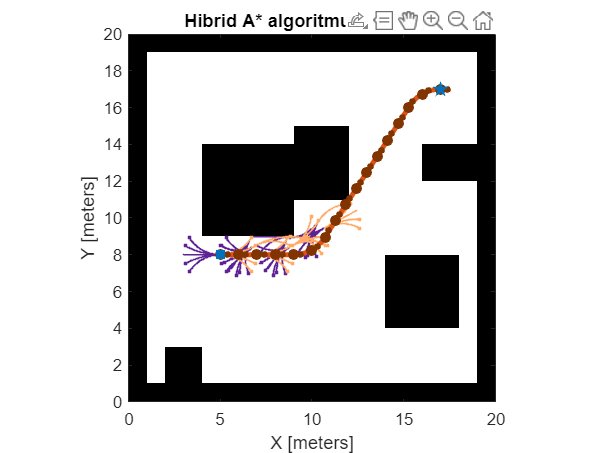


show(planner)
title("Hibrid A* algoritmus, 4. Pálya")

Data = [refpath.States(:,1) refpath.States(:,2)]

Data =     5.0000    8.0000
    6.0000    8.0000
    7.0000    8.0000
    8.0000    8.0000
    9.0000    8.0000
    9.9589    8.2448
   10.7091    8.9598
   11.2786    9.8398
   11.8480   10.7198
   12.4175   11.5998
